**HW #3**

In-Class Assignment:

PROBLEM 1:

(a) Take random sample of size 10 from N(2,1). This is your raw data. Calculate 95% CI of median using (use B=200, C=25) 

      1. Standard method 

      2. Bootstrap-t method 

      3. Bootstrap percentile interval 

Plot the histogram of the Bootstrap replications. Compare the three intervals in terms of the widths of the intervals. 

% initializing stuff
rng(1)
data = normrnd(2,1,1,10);
thetahat = median(data)

thetahat = 1.4343

alpha = 0.05;
B = 200;
C = 25;

% first bootstrap
[bootreps, bootsam] = bootstrp(B, @median, data);

% Standard CI
zlo = norminv(alpha/2);
zhi = norminv(1-alpha/2);
se = std(bootreps);

zLowCI = thetahat + zlo*se

zLowCI = 0.9374

zUpCI = thetahat + zhi*se

zUpCI = 1.9312


% Bootstrap-T CI
sehats = zeros(1,B);

for i = 1:B
    xstar = data(bootsam(:,i));
    sehats(i) = std(bootstrp(C,@median,xstar));
end

zvals = (bootreps - thetahat)./sehats;

k = B*alpha/2;
zvals = sort(zvals);
tlo = zvals(k);
thi = zvals(B-k);

tLowCI = thetahat + tlo*se

tLowCI = 1.2800

tUpCI = thetahat + thi*se

tUpCI = 2.2843


% Percentile Bootstrap CI
sbval = sort(bootreps);
pLowCI = sbval(k)

pLowCI = 1.2963

pUpCI = sbval(B-k)

pUpCI = 2.1948

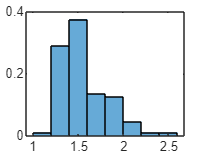


% plotting the above stuff
histogram(bootreps, "normalization", "probability")

(b) Repeat (a) 100 times and compare the coverages and stabilities. For stability calculate the standard deviations of the widths of Cis.  

     Coverage = (# of CI including the true value)/100 

% initializing coverage values
zCov = 0; tCov = 0; pCov = 0; reps = 100;

% empty lists for width of CI
zRange = zeros(1,reps); tRange = zeros(1,reps); pRange = zeros(1,reps);

% oh my goodness

rng("shuffle")
for i = 1:reps

    data = normrnd(2,1,1,10);
    thetahat1 = median(data);

    dataForRun = normrnd(2,1,1,10);

    [zInt, tInt, pInt] = allCI(dataForRun, @median);
    zRange(i) = zInt(2) - zInt(1);
    tRange(i) = tInt(2) - tInt(1);
    pRange(i) = pInt(2) - pInt(1);

    if (thetahat1 > zInt(1) && thetahat1 < zInt(2))
        zCov = zCov + 1;
    end

    if (thetahat1 > tInt(1) && thetahat1 < tInt(2))
        tCov = tCov + 1;
    end

    if (thetahat1 > pInt(1) && thetahat1 < pInt(2))
        pCov = pCov + 1;
    end
end

zStab = std(zRange)

zStab = 0.5320

tStab = std(tRange)

tStab = 1.0189

pStab = std(pRange)

pStab = 0.4761


zCov = zCov/reps

zCov = 0.8500

tCov = tCov/reps

tCov = 0.8800

pCov = pCov/reps

pCov = 0.9000

PROBLEM 2:

(a) For forearm data give three Bootstrap CI's (classical, Boot-t, percentile) for skewness, kurtosis, and central second moment. 

% import and transpose data
forearm = importdata('C:\Users\casti\OneDrive\Desktop\School_Stuff\Masters_Stuff\STAT 572\CompStatsToolboxV2\forearm.mat');
forearm = forearm';

% apply modified function
[zInt_Skew, tInt_Skew, pInt_Skew] = allCI(forearm, @skewness);
[zInt_Kurt, tInt_Kurt, pInt_Kurt] = allCI(forearm, @kurtosis);
[zInt_MOM, tInt_MOM, pInt_MOM] = allCI(forearm, @mom);

% Skewness CI
zInt_Skew

zInt_Skew =    -0.3884    0.1699


tInt_Skew

zInt_Kurt =     2.1588    2.9852


pInt_Skew

zInt_MOM =     1.0106    1.4824



% Kurtosis CI
zInt_Kurt

tInt_Skew =    -0.4113    0.2102


tInt_Kurt

tInt_Kurt =     2.1747    3.1029


pInt_Kurt

tInt_MOM =     1.0420    1.4180



% MOM CI
zInt_MOM

pInt_Skew =    -0.3682    0.1646


tInt_MOM

pInt_Kurt =     2.2022    3.0661


pInt_MOM

pInt_MOM =     0.9994    1.4538


(b) Repeat (a) 100 times and compare the coverages and stabilities. For stability calculate the standard deviations of the widths of Cis. 

% import and transpose data
forearm = importdata('C:\Users\casti\OneDrive\Desktop\School_Stuff\Masters_Stuff\STAT 572\CompStatsToolboxV2\forearm.mat');
forearm = forearm';

[zStab_Kurt, tStab_Kurt, pStab_Kurt, zCov_Kurt, tCov_Kurt, pCov_Kurt] = CILoops(100, forearm, @kurtosis)

zStab_Kurt = 0.0459

tStab_Kurt = 0.2347

pStab_Kurt = 0.0587

zCov_Kurt = 0.9300

tCov_Kurt = 0.9100

pCov_Kurt = 0.9100

[zStab_Skew, tStab_Skew, pStab_Skew, zCov_Skew, tCov_Skew, pCov_Skew] = CILoops(100, forearm, @skewness)

zStab_Skew = 0.0282

tStab_Skew = 0.1334

pStab_Skew = 0.0384

zCov_Skew = 0.9500

tCov_Skew = 0.8900

pCov_Skew = 0.9400

[zStab_MOM, tStab_MOM, pStab_MOM, zCov_MOM, tCov_MOM, pCov_MOM] = CILoops(100, forearm, @mom)

zStab_MOM = 0.0246

tStab_MOM = 0.1143

pStab_MOM = 0.0338

zCov_MOM = 1

tCov_MOM = 0.9500

pCov_MOM = 0.9700

Book Problem 7.12:

Completion of this problem requires the use of the **lawpop** data. The problem asks to devise a test statistic to test for the significance of correlation between LSAT scores and correlation of corresponding GPA. Once done, obtain a random sample from the population to perform hypothesis testing. Do MC simulation of only Type I error.

H0: thetahat = 0

HA: thetahat != 0

% import data and set variables.
lawpop = importdata("C:\Users\casti\OneDrive\Desktop\School_Stuff\Masters_Stuff\STAT 572\CompStatsToolboxV2\lawpop.mat");
gpa = lawpop.gpa;
lsat = lawpop.lsat;
thetahat = tstar(gpa, lsat) % observed test-statistic

thetahat = 10.4591

n = length(gpa);
M = 1000;
alpha = 0.05;

% distribution of data
mu1 = mean(gpa); sig1 = std(gpa);
mu2 = mean(lsat); sig2 = std(lsat);
mus = [mu1, mu2];
sigs = [sig1, sig2];

% Monte Carlo trials
tS = zeros(1,M);
for i = 1:M
    dfRS = mvnrnd(mus, sigs, n);
    tS(i) = tstar(dfRS(:,1), dfRS(:,2));
end

% critical value
tS = sort(tS);
mcLow = tS(round((alpha/2)*M))

mcLow = -1.9883

mcUp = tS(round((1-alpha))*M)

mcUp = 3.1818


% calculating Type I Error
cv1 = norminv(alpha/2, 0, 1)

cv1 = -1.9600

cv2 = norminv(1-(alpha/2), 0, 1)

cv2 = 1.9600

alph_instance = 0;

for i = 1:M
    dfRS = mvnrnd(mus, sigs, n);
    t_stats = tstar(dfRS(:,1), dfRS(:,2));
    if t_stats <= cv1 || t_stats >= cv2
        alph_instance = alph_instance + 1;
    end
end

alphahat = alph_instance/M

alphahat = 0.0430